# LAB 1: INTRODUCTION TO MATLAB

%---------------------------------------
% Fill in your student Name and ID.
Students.Name = 'Seyed Yazdan Zinati';
Students.ID = '260928077';
%---------------------------------------

## **0. Objectives**

This lab is divided into two parts. The first part is an introduction to some useful functions in `MATLAB` and how they will be used in the series of following labs. The second part is an application of how to calculate Laplace and inverse Laplace using `MATLAB`. Each part has questions at the end that need to be completed.

## **1. How to Submit Lab Reports**

A `MATLAB` LiveScript is an interactive document that combines `MATLAB` code with embedded output, formatted text, equations, and images in a single environment called the Live Editor. LiveScripts are stored using the LiveScript file format in a file with a `.mlx` extension.

Labs consist of a `MATLAB` LiveScript file. You should read and answer the questions inside the LiveScript document. At the end of the lab:

- Fill your `Name`, and `ID` at the header of the LiveScript.

- Ensure that the LiveScript document runs without errors.

- Export the LiveScript to a PDF format (Click on the arrow under the save icon).

- Submit the LiveScript and the generated PDF in myCourses.

- If requested, attach any auto-generated MAT-file (explained in section 2.4).

## **2. Useful Functions**

## *2.1. Documentation in* `MATLAB`

All the functions in `MATLAB` are accompanied with detailed documentation about their usage. You can access inline documentation by typing `help` followed by the function name. For example

help abs

 abs    Absolute value.
    abs(X) is the absolute value of the elements of X. When
    X is complex, abs(X) is the complex modulus (magnitude) of
    the elements of X.
 
    See also sign, angle, unwrap, hypot.

    Other functions named abs



A more complete documentation can be also obtained by using the `doc` command. For example

doc abs

## *2.2. Arrays in* `MATLAB`

Matrices and arrays are the fundamental representation of information and data in `MATLAB`. For a basic overview of matrix and array manipulation, you can refer to `MATLAB` on-line documentation: [Matrices and Arrays](https://www.mathworks.com/help/matlab/learn_matlab/matrices-and-arrays.html), and if needed watch the following video [Working with Arrays in MATLAB](https://www.mathworks.com/videos/working-with-arrays-in-matlab-101637.html).

Arrays will be used to model a discrete-time signal. An example of a discrete-time signal is:

dt = 0.01; % timestep of discrete signal in seconds
T = 10; % Final value of the time signal in seconds

% This creates an array |t = [0, 0.01, 0.02, 0.03, ..., 9.98, 9.99, 10.0]|.
t = 0:dt:T; % time signal

A sine wave signal of amplitude 1 and period 1 rad/second


$$ x_1(t) = \sin(2 \pi t) $$


can be written as

x1 = sin(2*pi*t);

Logical operations can be used to construct a desired signal. For example, the following signal


$$x_2(t) = \begin{cases}  t, & 0 \leq t < 5 \\ -t+10,  & t \geq
5\end{cases}$$


Can be written as

x2 = zeros(size(t)); % create a zero signal with the same size as time
x2(t < 5) = t(t < 5); % value is equal to time, but only when time < 5
x2(t >= 5) = -t(t >= 5) + 10; % value is equal to -time+10, but only when time >= 5

Other useful functions are: `size`, `length`, `ones`. You can use `MATLAB` help for more information.

## *2.3. Plotting signals*

In order to present results you can use the `plot` function. `plot(X,Y)` creates a 2-D line plot of the data in Y versus the corresponding values in X.

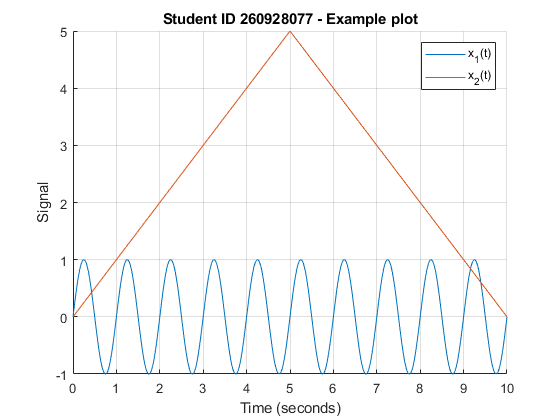

figure;
hold on;
grid on;
plot(t, x1);
plot(t, x2);
title(sprintf('Student ID %s - Example plot', Students.ID));
xlabel('Time (seconds)')
ylabel('Signal')
legend('x_1(t)', 'x_2(t)')
hold off;

## *2.4. Matrices in* `MATLAB`

Matrices are extensions of arrays. They will be used to represent linear systems in a state space form.

For example to represent the matrix A:


$$ A = \pmatrix{8 & 1 & 6 \cr 3 & 5 & 7 \cr 4 & 9 & 2} $$


We write

A = [8, 1, 6; 3, 5, 7; 4, 9, 2]

A =      8     1     6
     3     5     7
     4     9     2


Determinant of A can be obtained by:

det(A)

ans = -360

Eigenvalues of A can be obtained by:

eig(A)

ans =    15.0000
    4.8990
   -4.8990


Inverse of A can be obtained by:

inv(A)

ans =     0.1472   -0.1444    0.0639
   -0.0611    0.0222    0.1056
   -0.0194    0.1889   -0.1028


## *2.5. Saving/loading data*

In `MATLAB` you can save any or all the variables in the current workspace to a MAT-file (.mat). You can then reuse the workspace variables later during the current MATLAB session or during another session by loading the saved MAT-file.

For example, to save a variable, you can use:

example = sprintf('A variable generated by Student ID <%s>', Students.ID);
save('Lab01.mat', 'example')

Now we remove the variable `example` from the workspace.

clear example

You can recover the variable `example` to the workspace from the MAT-file, by doing

load('Lab01.mat', 'example')
display(example)

example = 'A variable generated by Student ID <260928077>'

For hardware labs (labs that requires the use of external hardware), it is possible to save result of your manipulation in this manner. The resulting file can be used to re-examine your data, or change your plots.

## *Question 1 (4 marks)*

Answer the following questions in the LiveScript. (Observe that if you finish an expression with a semicolon the results will not show in your report. Use semicolons at the end of your expression with the intention to show or hide your answer)

- Define a time signal from 0 to 10 seconds, with a time step of 0.1 second.

dt = 0.1; % Timestemps of 0.1s of the discrete signal
T = 10; % Final value of time in seconds 
t = 0:dt:10 % Time signal

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


- Define a unit signal equals to 1 from 0 to 10 second. (The unit signal should have the same size as time)


$$y_1(t) = 1, \quad t \geq 0$$


y1 = ones(size(t)) % Create a 1 signal with the same size as time

y1 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


- Define a delayed signal equals zero from 0 to 5 seconds and to -1 from 5 to 10 seconds.


$$y_2(t) = \begin{cases}  0, & t < 5 \\  -1,  & t \geq 5\end{cases}$$


y2(t<5) = 0 % Case when t<5

y2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y2(t>=5) = -1 %Case when t>=5

y2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


- Define a ramp signal with slope equals 0.1.


$$y_3(t) = 0.1 t, \quad t \geq 0$$


y3(t>=0) = 0.1*t 

y3 =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


- Define a decaying exponential signal with time constant of 10 second.


$$y_4(t) = e^{-\frac{t}{10}}$$


y4 = 1*exp(-t/10) % Multiplication by 1 to convert symbolic function to numeric

y4 =     1.0000    0.9900    0.9802    0.9704    0.9608    0.9512    0.9418    0.9324    0.9231    0.9139    0.9048    0.8958    0.8869    0.8781    0.8694    0.8607    0.8521    0.8437    0.8353    0.8270    0.8187    0.8106    0.8025    0.7945    0.7866    0.7788    0.7711    0.7634    0.7558    0.7483    0.7408    0.7334    0.7261    0.7189    0.7118    0.7047    0.6977    0.6907    0.6839    0.6771    0.6703    0.6637    0.6570    0.6505    0.6440    0.6376    0.6313    0.6250    0.6188    0.6126


- Plot in the same graph the signals ($y_1(t)$, $y_2(t)$, $y_3(t)$, and $y_4(t)$) versus the time signal.

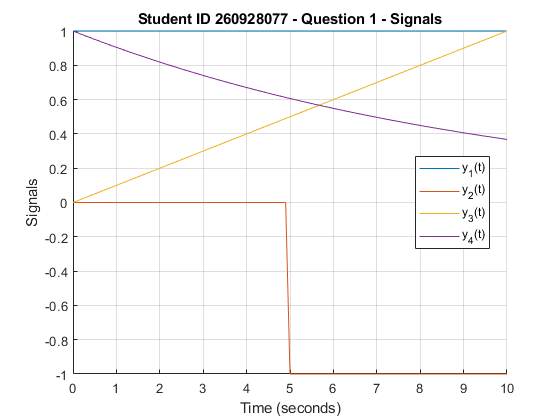

figure;
hold on;
grid on;
% Fill in your plots command

plot(t, y1);
plot(t, y2);
plot(t, y3);
plot(t, y4);

title(sprintf('Student ID %s - Question 1 - Signals', Students.ID));
xlabel('Time (seconds)')
ylabel('Signals')
legend('y_1(t)', 'y_2(t)', 'y_3(t)', 'y_4(t)', 'location', 'best')

hold off;

## **3. Laplace transforms**

Recall that the (one-sided) Laplace transform of a function $f(t)$ is defined as:


$$ F(s) = \int_{0^-}^{+\infty} f(t) e^{-s t} dt $$


In this section, we will learn how to compute the Laplace and inverse Laplace transforms using `MATLAB`.

## *3.1. Computing Laplace Transform*

The command `laplace` in `MATLAB` provides an easy way to calculate the Laplace transform $F(s)$ of a function $f(t)$. To use `laplace`, first you need to specify that the variable $t$ and $s$ are symbolic ones. This is done with the command:

syms t s

Then, we define the function $f(t)$.

f = exp(-t)

$$f = {\mathrm{e}}^{-t}$$

Finally, we compute the Laplace transform using the function `laplace`

F = laplace(f, t, s)

$$F = \frac{1}{s+1}$$

To get more information about the `laplace` function, type:

help laplace

--- help for sym/laplace ---

 laplace Laplace transform.
    L = laplace(F) is the Laplace transform of the sym F with default
    independent variable t.  The default return is a function of s.
    If F = F(s), then laplace returns a function of z:  L = L(z).
    By definition, L(s) = int(F(t)*exp(-s*t),t,0,inf).
 
    L = laplace(F,z) makes L a function of z instead of the default s:
    laplace(F,z) <=> L(z) = int(F(t)*exp(-z*t),t,0,inf).
 
    L = laplace(F,w,u) makes L a function of u instead of the
    default s (integration with respect to w).
    laplace(F,w,u) <=> L(u) = int(F(w)*exp(-u*w),w,0,inf).
 
    Examples:
     syms a s t w x F(t)
     laplace(t^5)          returns   120/s^6
     laplace(exp(a*s))     returns   -1/(a-z)
     laplace(sin(w*x),t)   returns   w/(t^2+w^2)
     laplace(cos(x*w),w,t) returns   t/(t^2+x^2)
     laplace(x^(3

Often, using `laplace` function gives an expression that is mathematically correct, but not in its simplest form. In such cases, the function `simplify` can be used to simplify the expression. For example:

simplify(2/(s + 1)-s/(s + 1)^2)

$$ans = \frac{s+2}{{\left(s+1\right)}^{2}}$$

To get more information about the `simplify` function, type:

help sym/simplify

 simplify Symbolic simplification.
    simplify(S) simplifies each element of the symbolic matrix S.
    
    simplify(S,N) or, equivalently, simplify(S,'Steps',N),
    searches for a simplification in N steps. The default value of N is 1.
    
    simplify(S,'Seconds',T) aborts the search for a simpler version
    at the next end of a simplification step after T seconds. The results
    will depend on the speed and system load of your computer and may
    not be reproducible.
    
    simplify(S,'IgnoreAnalyticConstraints',VAL) controls the level of 
    mathematical rigor to use on the analytical constraints while simplifying 
    (branch cuts, division by zero, etc). The options for VAL are TRUE or 
    FALSE. Specify TRUE to relax the level of mathematical rigor
    in the rewriting process. The default is FALSE.
    
    simplify(S, 'Criterion', 'preferReal') 
   

## *Question 2 (2 marks)*

Write the symbolic expression of the following functions (you can use the symbolic variables `t` and `s` defined previously):

- $f_1(t) = \delta(t)$ ($\delta(t)$ is the dirac function, use `help dirac` for more information)

- 
$$f_2(t) = t^2 + 4 t + 1$$


- 
$$f_3(t) = te^{-t} + 0.5e^{-t} + e^{-3t}$$


- 
$$f_4(t) = \sin(2t) + \cos^2(t)$$


- 
$$f_5(t) = e^{-t}\sin(5 t + \frac{\pi}{3})+t^2 e^{-2t}$$


f1 = dirac(t)

$$f1 = \delta (t)$$

f2 = (t.^2)+(4*t)+1

$$f2 = t^{2}+4\,t+1$$

f3 = (t*exp(-t))+(0.5*exp(-t))+(exp(-3*t))

$$f3 = \frac{{\mathrm{e}}^{-t}}{2}+{\mathrm{e}}^{-3\,t}+t\,{\mathrm{e}}^{-t}$$

f4 = sin(2*t)+cos(t).^2

$$f4 = {\cos\left(t\right)}^{2}+\sin\left(2\,t\right)$$

f5 = exp(-t)*sin(5*t+pi/3)+t.^2*exp(-2*t)

$$f5 = t^{2}\,{\mathrm{e}}^{-2\,t}+\sin\left(5\,t+\frac{\pi }{3}\right)\,{\mathrm{e}}^{-t}$$

## *Question 3 (2 marks)*

Use `MATLAB` to compute the Laplace transform of the functions defined in *Question 2*. Use `simplify` to simplify the symbolic expression if needed.

F1 = laplace(f1, t, s)

$$F1 = 1$$

F2 = simplify(laplace(f2, t, s))

$$F2 = \frac{s^{2}+4\,s+2}{s^{3}}$$

F3 = simplify(laplace(f3, t, s))

$$F3 = \frac{3\,s^{2}+10\,s+11}{2\,{\left(s+1\right)}^{2}\,\left(s+3\right)}$$

F4 = simplify(laplace(f4, t, s))

$$F4 = \frac{s^{2}+2\,s+2}{s\,\left(s^{2}+4\right)}$$

F5 = simplify(laplace(f5, t, s))

$$F5 = \frac{2}{{\left(s+2\right)}^{3}}+\frac{5}{2\,\left({\left(s+1\right)}^{2}+25\right)}+\frac{\sqrt{3}\,\left(s+1\right)}{2\,\left({\left(s+1\right)}^{2}+25\right)}$$

## *3.2. Computing inverse Laplace transforms*

The function `ilaplace` computes the inverse Laplace transform. Consider the Laplace transform `F` computed earlier. We can compute the inverse Laplace transform (note that the `t` and `s` are already defined as symbols)

Example

ilaplace(F, s, t);

## *Question 4 (2 marks)*

Use `MATLAB` to calculate the inverse Laplace transform of the following expressions. Use `simplify` to simplify the symbolic expression if needed.

- 
$$G_1(s) = \displaystyle \frac{1}{s}$$


- 
$$G_2(s) = \displaystyle \frac{1}{s(s+1)}$$


- 
$$G_3(s) = \displaystyle \frac{5}{s^2+25}$$


- 
$$G_4(s) = \displaystyle \frac{10s+1}{s^2+2s+10}$$


- 
$$G_5(s) = \displaystyle \frac{2(s+1)(s^2+4)}{(s^2+4s+1)(s^2+9)}$$


G1 = 1/s

$$G1 = \frac{1}{s}$$

G2 = 1/(s*(s+1))

$$G2 = \frac{1}{s\,\left(s+1\right)}$$

G3 = 5/(s.^2+25)

$$G3 = \frac{5}{s^{2}+25}$$

G4 = (10*s+1)/(s.^2+2*s+10)

$$G4 = \frac{10\,s+1}{s^{2}+2\,s+10}$$

G5 = (2*(s+1)*(s.^2+4))/(((s.^2)+4*s+1)*(s.^2+9))

$$G5 = \frac{\left(2\,s+2\right)\,\left(s^{2}+4\right)}{\left(s^{2}+9\right)\,\left(s^{2}+4\,s+1\right)}$$


g1 = ilaplace(G1, s, t)

$$g1 = 1$$

g2 = ilaplace(G2, s, t)

$$g2 = 1-{\mathrm{e}}^{-t}$$

g3 = ilaplace(G3, s, t)

$$g3 = \sin\left(5\,t\right)$$

g4 = ilaplace(G4, s, t)

$$g4 = 10\,{\mathrm{e}}^{-t}\,\left(\cos\left(3\,t\right)-\frac{3\,\sin\left(3\,t\right)}{10}\right)$$

g5 = ilaplace(G5, s, t)

$$g5 = \frac{15\,\cos\left(3\,t\right)}{26}-\frac{35\,\sin\left(3\,t\right)}{78}+\frac{37\,{\mathrm{e}}^{-2\,t}\,\left(\cosh\left(\sqrt{3}\,t\right)-\frac{47\,\sqrt{3}\,\sinh\left(\sqrt{3}\,t\right)}{111}\right)}{26}$$